# Basic uasge

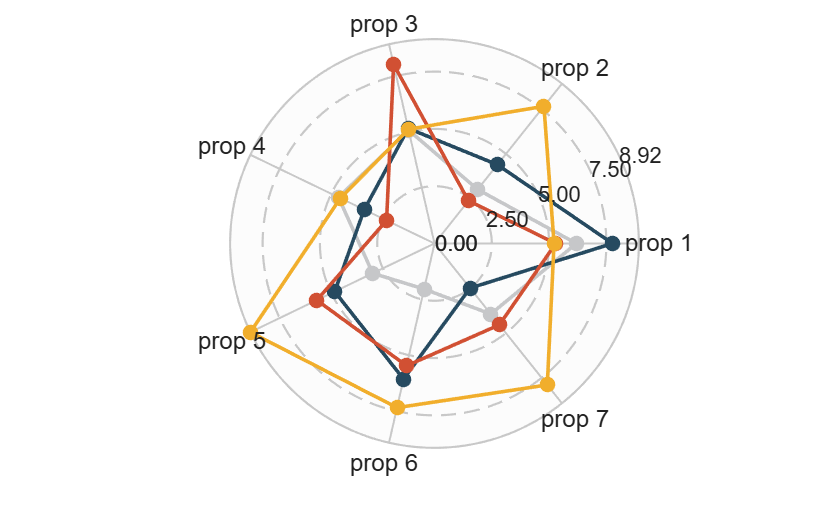

figure()
X = randi([2, 8], [4, 7]) + rand([4, 7]);

% Create radar chart object
RC1 = radarChart(X);

% Draw radar chart and display legend
RC1 = RC1.draw();

# Rendering type

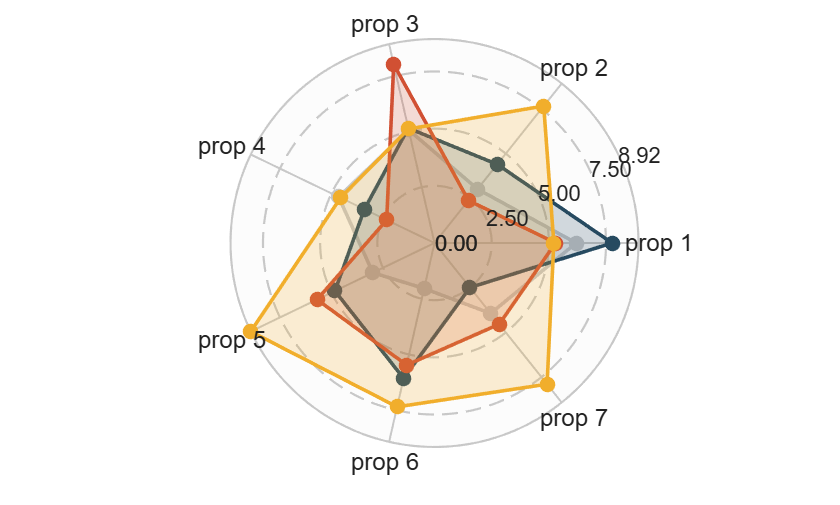

figure()
RC1.setType("Both");

# R limit and R tick

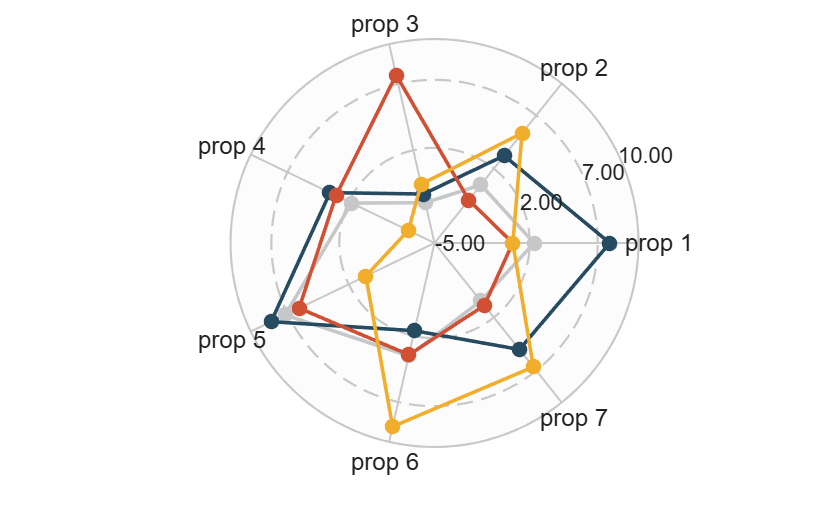

figure()
X = randi([-3, 8], [4, 7]) + rand([4, 7]);

% Create radar chart object.
RC2 = radarChart(X);

% Set R-axis limit and ticks.
RC2.RLim = [-5,10];
RC2.RTick = [-5,2,7,10];

% Draw radar chart.
RC2 = RC2.draw();

# Legend

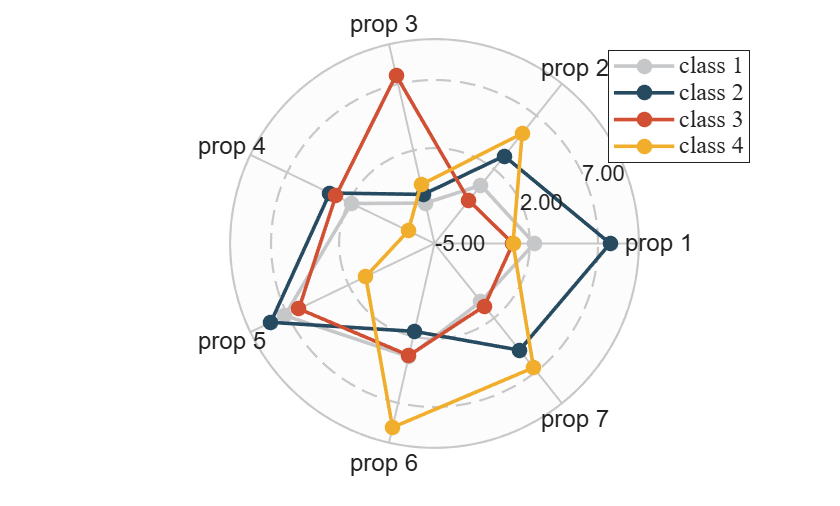

figure()
RC2 = RC2.legend();

# Property and Class names

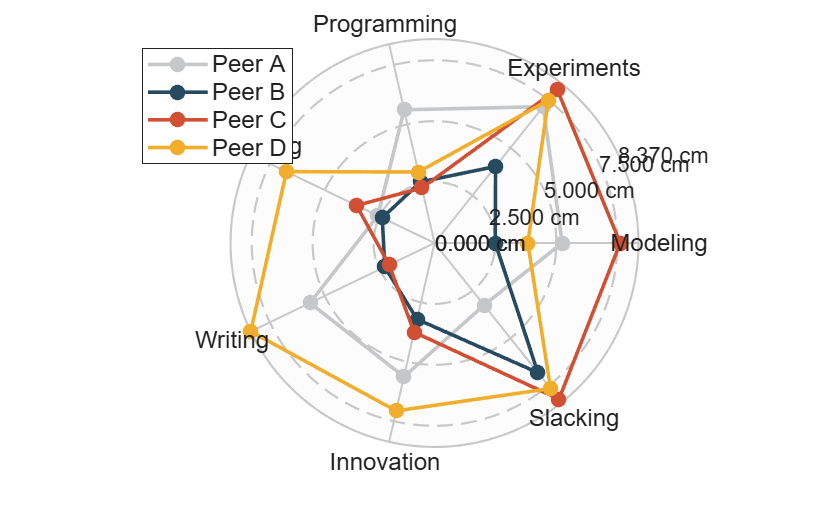

figure()
X = randi([2, 8], [4, 7]) + rand([4, 7]);
% Create radar chart object.
RC3 = radarChart(X);

% Set property names and class names.
RC3.PropName = {'Modeling', 'Experiments', 'Programming', 'Summarizing', 'Writing', 'Innovation', 'Slacking'};
RC3.ClassName = {'Peer A', 'Peer B', 'Peer C', 'Peer D'};

RC3.RTickLabelFormat = @(X) sprintf('%.3f cm',X);

% Draw radar chart and display legend.
RC3 = RC3.draw();
RC3 = RC3.legend();

# Font

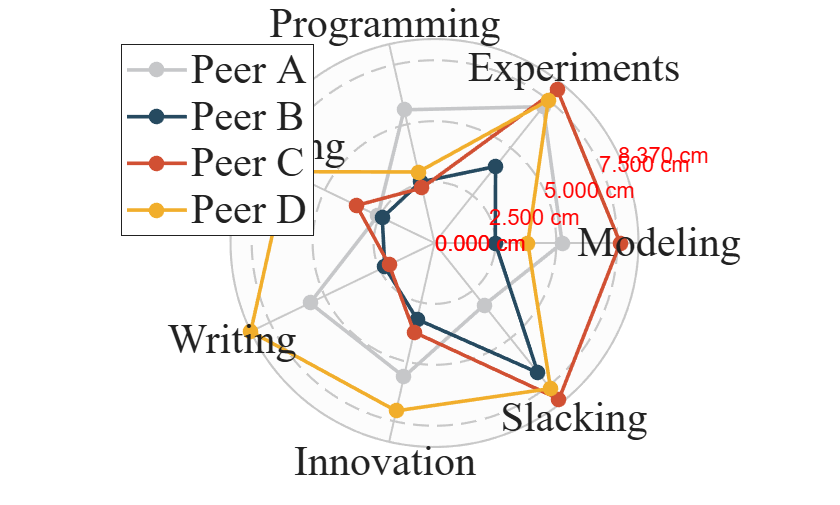

RC3.setLegend('FontSize', 21, 'FontName', 'Times New Roman');
RC3.setPropLabel('FontSize', 21, 'FontName', 'Times New Roman');
RC3.setRLabel('Color', 'r');

# Color and Edge

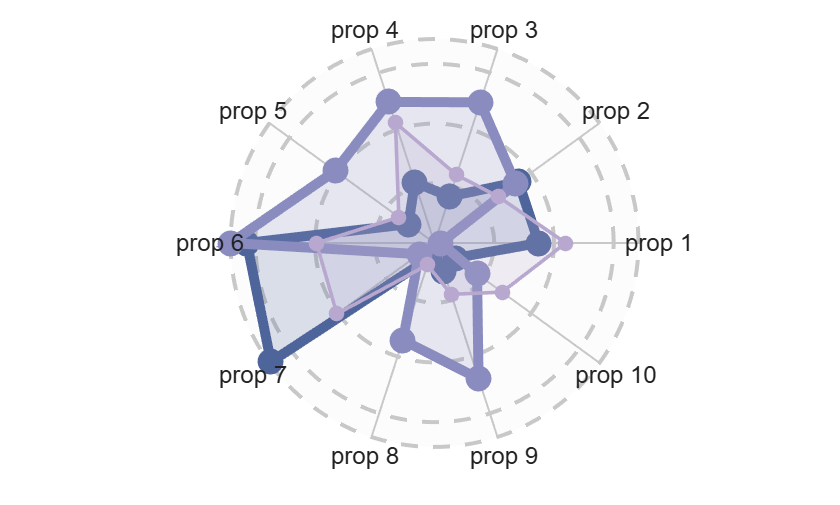

figure()
rng(2)
X = rand([3, 10]);
% Initialize radar chart object with patch rendering type.
RC4 = radarChart(X, 'Type','Both');

% Set color for radar chart.
RC4.CList = [78 101 155;
    138 140 191;
    184 168 207;
    231 188 198;
    253 207 158;
    239 164 132;
    182 118 108]./255;

RC4 = RC4.draw();
RC4.setPatchN(1, 'LineWidth', 5, 'MarkerSize', 8);  % Format class 1
RC4.setPatchN(2, 'LineWidth', 5, 'MarkerSize', 8);  % Format class 2
RC4.setRTick('LineWidth', 2);                                      % Radial tick mark thickness.
RC4.setRLabel('Color', 'none');                                    % Hide radial axis labels.
RC4.setBkg('EdgeColor', 'none');                                   % Remove background grid borders.